# Practica 7:  Métodos de integración numérica.

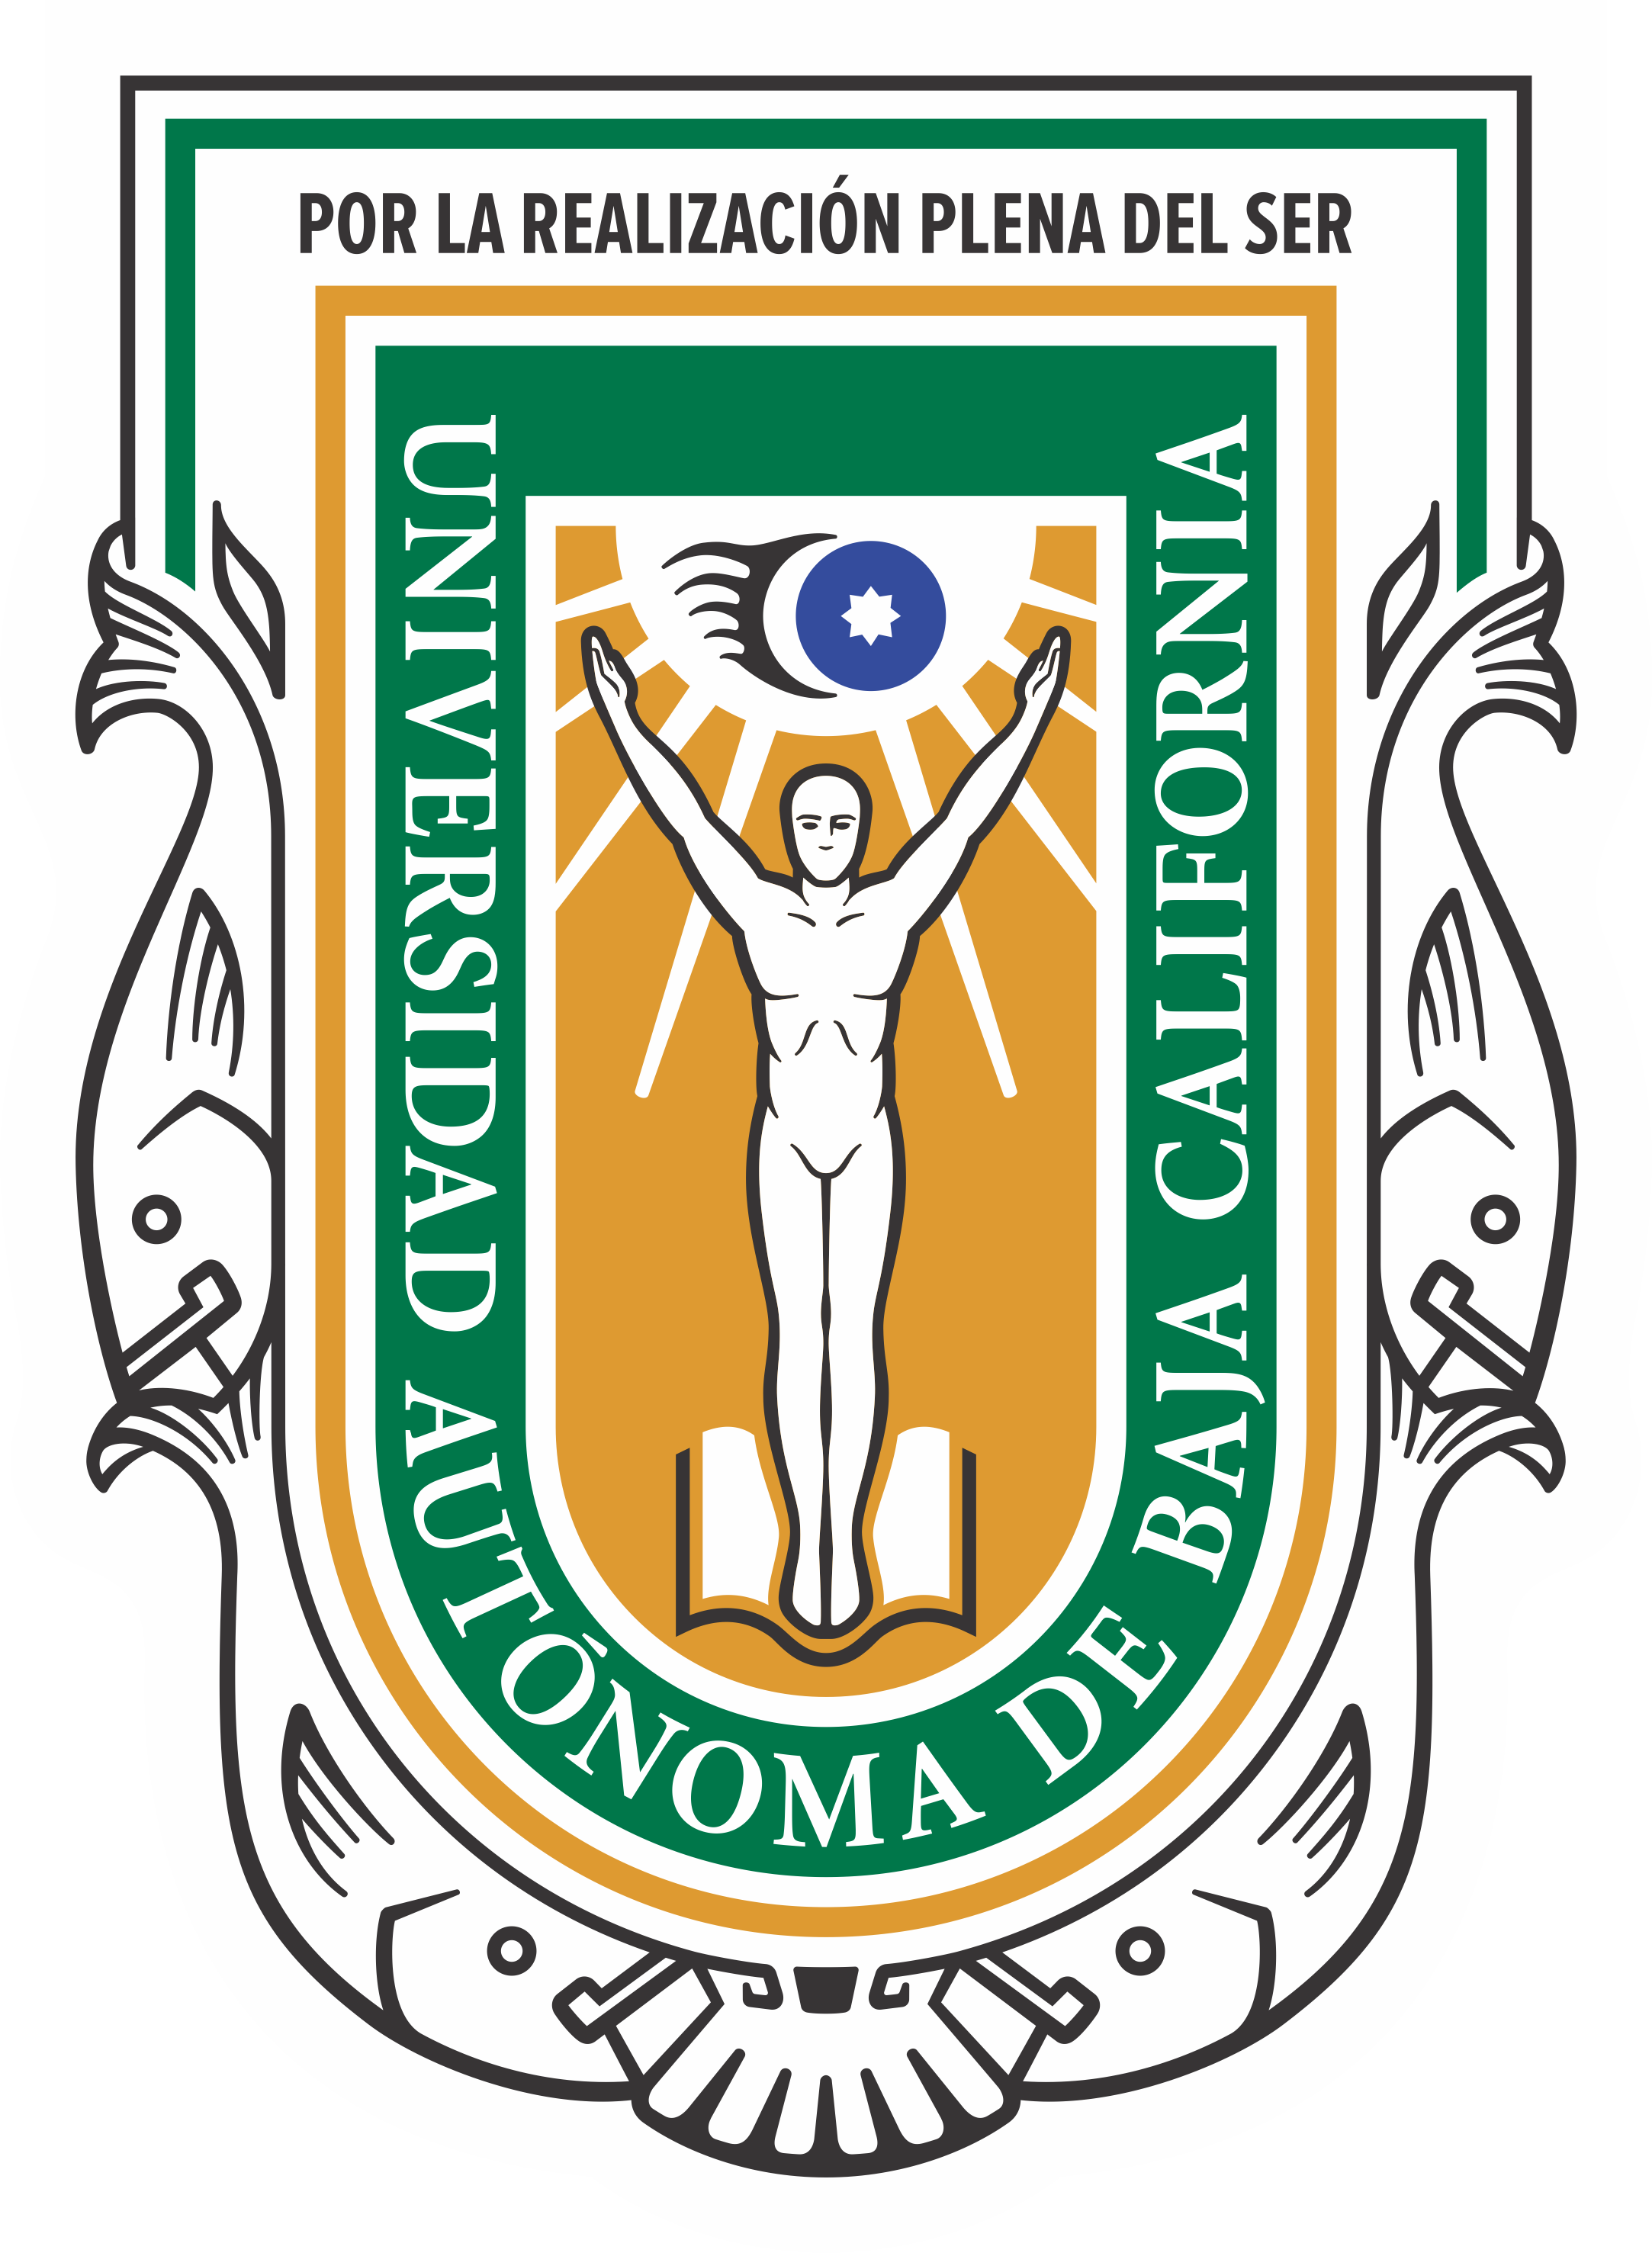

Nombre: Andres Eduardo Fabara Caicedo

Materia: Sistemas de Control

Fecha: Octubre/01/2025

`Profesor: `Sistemas de Control

Profesor: Laura Jimenez Beristain

### Introduccion

#### Parte 1.

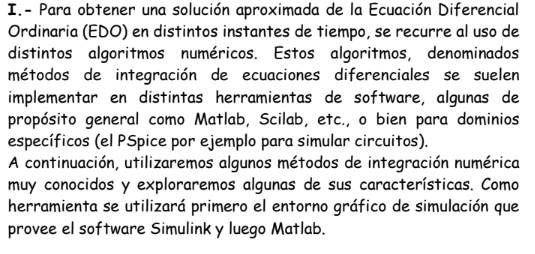

#### Parte 2.

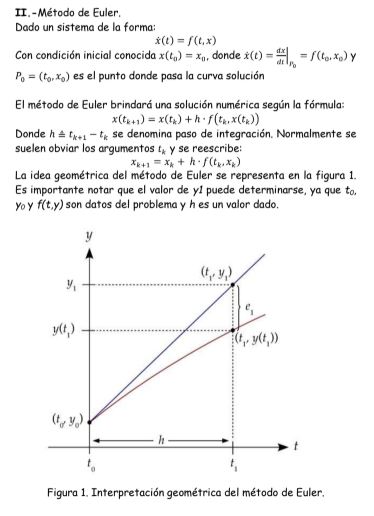

#### Parte 3.

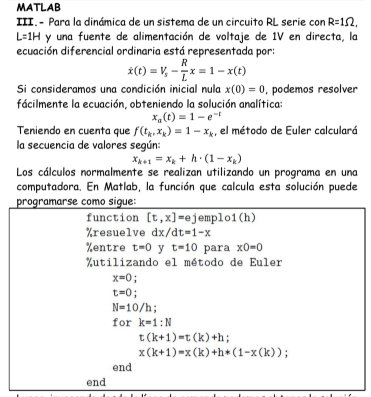

function [t,x]=ejemplo1(h)
    % Resuelve dx/dt = 1 - x
    % Entre t = 0 y t = 10 para x0 = 0
    % Utilizando el método de Euler
    x = 0;
    t = 0;
    N = 10/h;
    for k = 1:N
        t(k+1) = t(k) + h;
        x(k+1) = x(k) + h*(1 - x(k));
    end
end


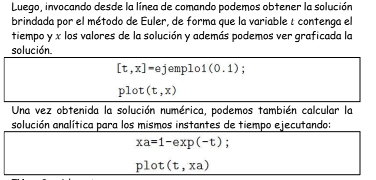

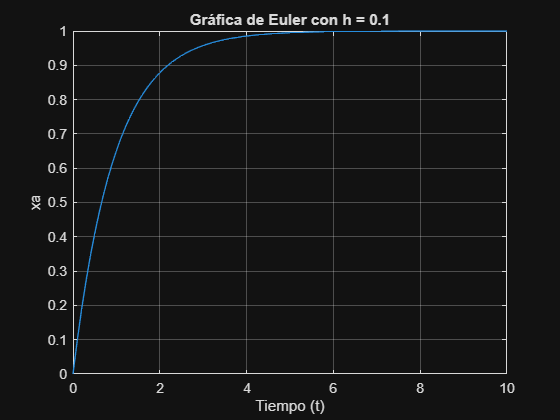

[t,x]=ejemplo1(0.1);
plot(t,x)
title('Gráfica de Euler con h = 0.1');
xlabel('Tiempo (t)');
ylabel('xa');
grid on;

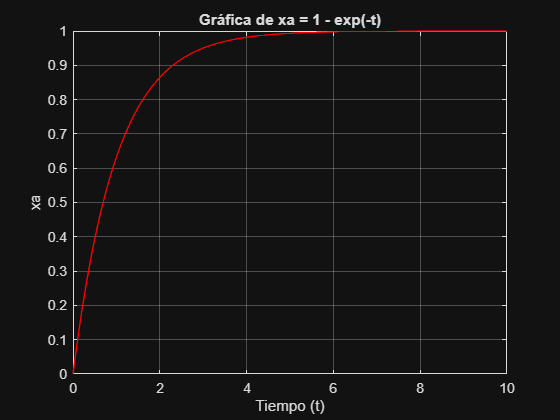

xa = 1 - exp(-t);
plot(t, xa, 'Color', "r")
title('Gráfica de xa = 1 - exp(-t)');
xlabel('Tiempo (t)');
ylabel('xa');
grid on;

#### Parte 4.

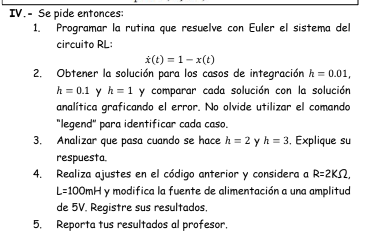

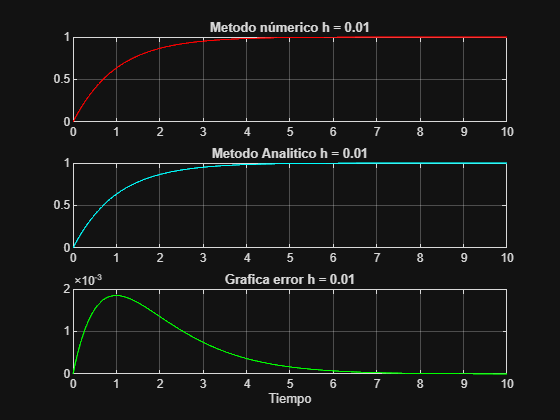

%%Puntos 1 y 2
figure Name 'Parte IV h = 0.01';
 %Programar la rutina que resuelve con Euler el sistema del circuito RL 
subplot(3,1,1); 
 [t,x]=ejemplo1(0.01);
 plot(t,x, 'Color',"r");
 title("Metodo númerico h = 0.01");
 grid on;
 %Metodo Analitico
 subplot(3,1,2)
 xa = 1 - exp(-t);
 plot(t, xa, 'Color', "c")
 title("Metodo Analitico h = 0.01");
 grid on;
 %Error Metodo Analitico
 subplot(3,1,3);
 error = abs(x-xa);
 plot(t, error,'Color', "g");
 title("Grafica error h = 0.01");
 xlabel("Tiempo");
 grid on;

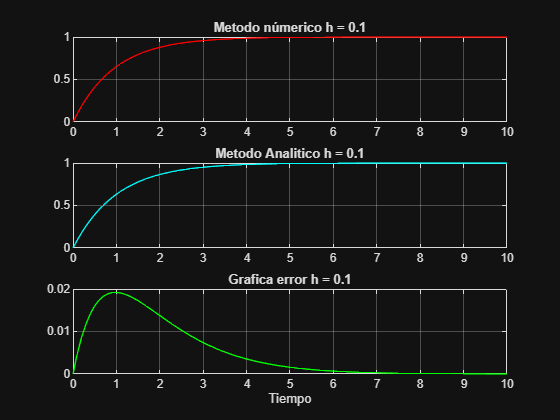

 figure Name 'Parte IV h = 0.1';
 %Programar la rutina que resuelve con Euler el sistema del circuito RL 
 subplot(3,1,1); 
 [t,x]=ejemplo1(0.1);
 plot(t,x, 'Color',"r");
 title("Metodo númerico h = 0.1");
 grid on;
 %Metodo Analitico
 subplot(3,1,2)
 xa = 1 - exp(-t);
 plot(t, xa, 'Color', "c")
 title("Metodo Analitico h = 0.1");
 grid on;
 %Error Metodo Analitico
 subplot(3,1,3);
 error = abs(x-xa);
 plot(t, error,'Color', "g");
 title("Grafica error h = 0.1");
 xlabel("Tiempo");
 grid on;

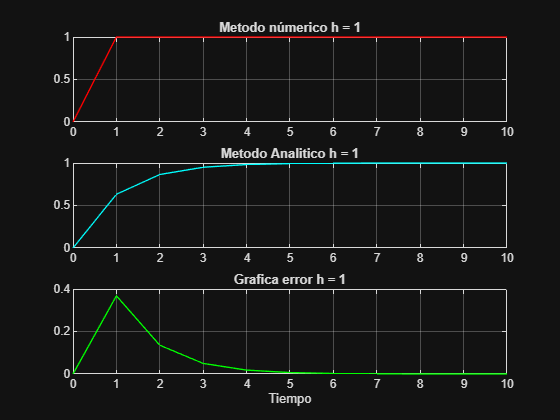

 figure Name 'Parte IV h = 1';
 %Programar la rutina que resuelve con Euler el sistema del circuito RL 
subplot(3,1,1); 
 [t,x]=ejemplo1(1);
 plot(t,x, 'Color',"r");
 title("Metodo númerico h = 1");
 grid on;
 %Metodo Analitico
 subplot(3,1,2)
 xa = 1 - exp(-t);
 plot(t, xa, 'Color', "c")
 title("Metodo Analitico h = 1");
 grid on;
 %Error Metodo Analitico
 subplot(3,1,3);
 error = abs(x-xa);
 plot(t, error,'Color', "g");
 title("Grafica error h = 1");
 xlabel("Tiempo");
 grid on;

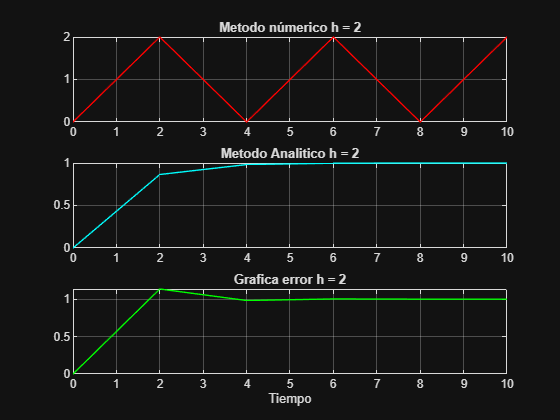

 %%Punto 3
 figure Name 'Parte IV h = 2';
 %Programar la rutina que resuelve con Euler el sistema del circuito RL 
subplot(3,1,1); 
 [t,x]=ejemplo1(2);
 plot(t,x, 'Color',"r");
 title("Metodo númerico h = 2");
 grid on;
 %Metodo Analitico
 subplot(3,1,2)
 xa = 1 - exp(-t);
 plot(t, xa, 'Color', "c")
 title("Metodo Analitico h = 2");
 grid on;
 %Error Metodo Analitico
 subplot(3,1,3);
 error = abs(x-xa);
 plot(t, error,'Color', "g");
 title("Grafica error h = 2");
 xlabel("Tiempo");
 grid on;

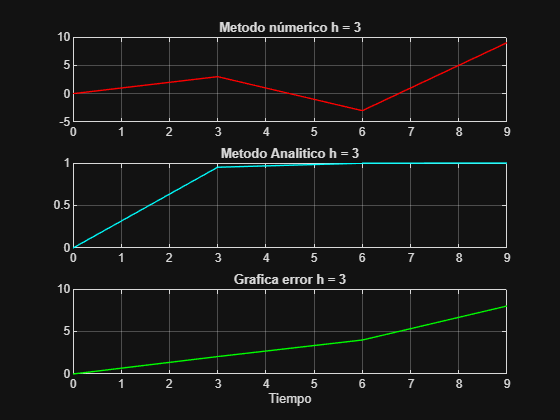

 %%Punto 3
 figure Name 'Parte IV h = 3';
 %Programar la rutina que resuelve con Euler el sistema del circuito RL 
 subplot(3,1,1); 
 [t,x]=ejemplo1(3);
 plot(t,x, 'Color',"r");
 title("Metodo númerico h = 3");
 grid on;
 %Metodo Analitico
 subplot(3,1,2)
 xa = 1 - exp(-t);
 plot(t, xa, 'Color', "c")
 title("Metodo Analitico h = 3");
 grid on;
 %Error Metodo Analitico
 subplot(3,1,3);
 error = abs(x-xa);
 plot(t, error,'Color', "g");
 title("Grafica error h = 3");
 xlabel("Tiempo");
 grid on;

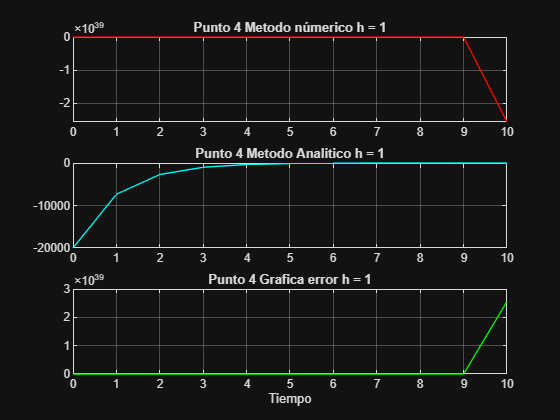

 %%Punto 4 y 5
 function [t,x]=Punto4(h);
    % Resuelve dx/dt = 1 - x
    % Entre t = 0 y t = 10 para x0 = 0
    % Utilizando el método de Euler
    x = 0;
    t = 0;
    N = 10/h;
    R = 2000;
    L = 0.1;
    Vs = 5;
    for k = 1:N
        t(k+1) = t(k) + h;
        x(k+1) = x(k) + h*(Vs - (R/L).*x(k));
    end
 end
 figure Name 'Parte IV punto 4 circuito RL';
 %Programar la rutina que resuelve con Euler el sistema del circuito RL 
 subplot(3,1,1); 
 [t,x]=Punto4(1);
 plot(t,x, 'Color',"r");
 title("Punto 4 Metodo númerico h = 1");
 grid on;
 %Metodo Analitico
 subplot(3,1,2)
 xa = 5 - (2000/0.1).*exp(-t);
 plot(t, xa, 'Color', "c");
 title("Punto 4 Metodo Analitico h = 1");
 grid on;
 %Error Metodo Analitico
 subplot(3,1,3);
 error = abs(x-xa);
 plot(t, error,'Color', "g");
 title("Punto 4 Grafica error h = 1");
 xlabel("Tiempo");
 grid on;

#### Parte 5.

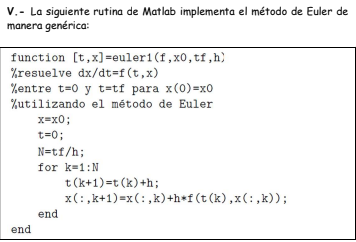

 function [t,x] = euler1(f,x0,tf,h);
 %resuelve dx/dt = f(t,x)
 %entre t=0 y t=tf para x(0) = x0
 %Utilizando el metodo de Euler
     x = x0;
     t = 0;
     N = tf/h;
     for k=1:N
         t(k+1) = t(k)+h;
         x(:, k+1) = x(:,k) + h*f(t(k), x(:,k));
     end
 end

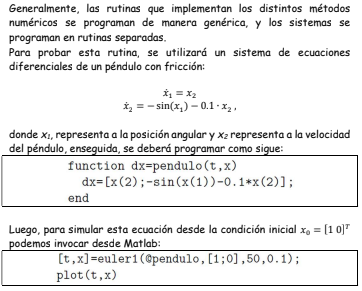

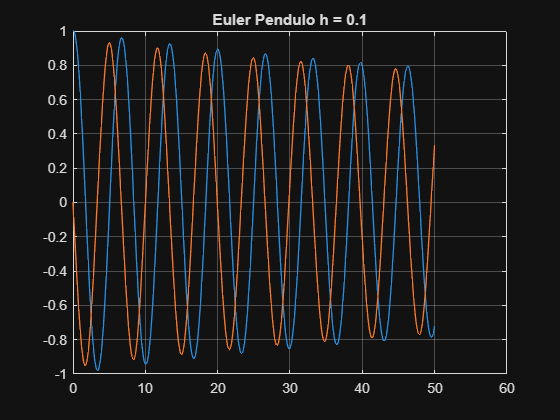

 function dx=pendulo(t,x);
   dx =[x(2);-sin(x(1))-0.1*x(2)];
 end
 figure
 [t,x] = euler1(@pendulo,[1;0],50, 0.1);
 plot(t,x)
 title("Euler Pendulo h = 0.1");
 grid on;

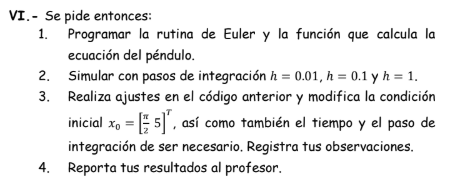

#### Parte 6.

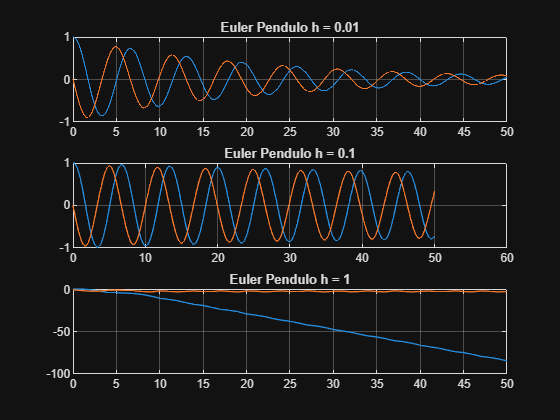

 %%Punto 1 y 2
figure
 subplot(3,1,1);
 [t,x] = euler1(@pendulo,[1;0],50, 0.01);
 plot(t,x)
 title("Euler Pendulo h = 0.01");
 grid on;
 subplot(3,1,2);
 [t,x] = euler1(@pendulo,[1;0],50, 0.1);
 plot(t,x)
 title("Euler Pendulo h = 0.1");
 grid on;
 subplot(3,1,3);
 [t,x] = euler1(@pendulo,[1;0],50, 1);
 plot(t,x)
 title("Euler Pendulo h = 1");
 grid on;

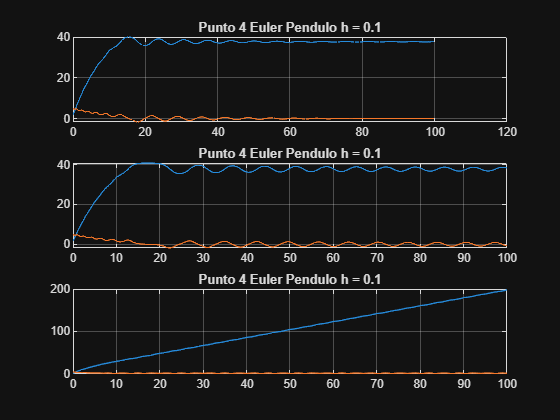

 %%Punto 4
figure
 subplot(3,1,1)
 [t,x] = euler1(@pendulo,[pi/2;5],100, 0.01);
 plot(t,x)
 title("Punto 4 Euler Pendulo h = 0.01");
 grid on;
 subplot(3,1,2)
 [t,x] = euler1(@pendulo,[pi/2;5],100, 0.1);
 plot(t,x)
 title("Punto 4 Euler Pendulo h = 0.1");
 grid on;
 subplot(3,1,3)
 [t,x] = euler1(@pendulo,[pi/2;5],100, 1);
 plot(t,x)
 title("Punto 4 Euler Pendulo h = 1");
 grid on;